# Diseño de un P, PI, PD y PID

 Sistema masa - resorte - amortiguador

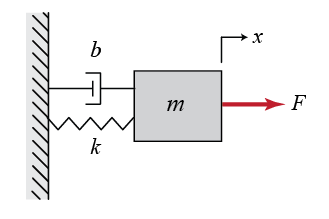

m=1Kg

b= 10N s/m

k=20 N/m

F= 1N


$$G(s)=\frac{1}{ms^2+bs+k}$$


Analice el sistema en lazo abierto.

Proponga objetivos de control

Calcule la función de transferencia del sistema en lazo cerrado para cada estructura de control (P, PI, PD y PID)

Seleccione la más adecuada y Justifique su decisión.

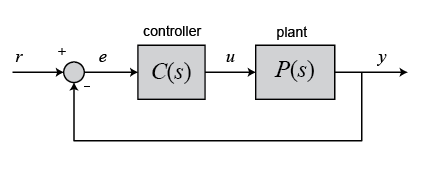

Analizar el sistema en lazo abierto

m=1

m = 1

b=10

b = 10

k=20

k = 20

num=[1]

num = 1

den=[m b k]

den =      1    10    20


G=tf(num,den)

G =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


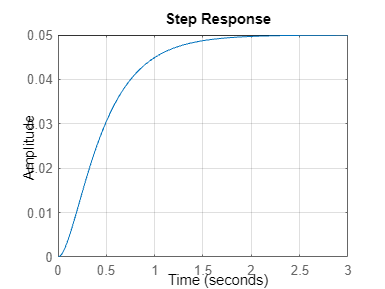

figure
step(G)
grid on

info=stepinfo(G)

info = struct with fields:
         RiseTime: 0.8843
    TransientTime: 1.5894
     SettlingTime: 1.5894
      SettlingMin: 0.0452
      SettlingMax: 0.0500
        Overshoot: 0
       Undershoot: 0
             Peak: 0.0500
         PeakTime: 3.2966


ts=info.RiseTime

ts = 0.8843

ess=1-(info.Peak)

ess = 0.9500

ts95=info.SettlingTime

ts95 = 1.5894

## Objetivos de control

- Eliminar el error en estado estacionario.

- ts y ts95 se mantengan con un valor similar, menor a 2seg.

## Controlador Kp

syms s kp
P = 1/(m*s^2 + b*s + k)

$$P = \frac{1}{s^{2}+10\,s+20}$$

kp=10

kp = 10

C=kp

C = 10

GLC=(C*P)/1+(C*P)*1

$$GLC = \frac{20}{s^{2}+10\,s+20}$$

GLC=eval(GLC)%Inv comando

$$GLC = \frac{20}{s^{2}+10\,s+20}$$

num=[2*kp]

num = 20

den=[m b k]

den =      1    10    20


GLC=tf(num,den)

GLC =
 
        20
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


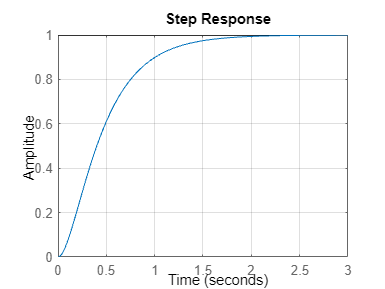

figure
step(GLC)
grid on

info=stepinfo(GLC)

info = struct with fields:
         RiseTime: 0.8843
    TransientTime: 1.5894
     SettlingTime: 1.5894
      SettlingMin: 0.9034
      SettlingMax: 0.9998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9998
         PeakTime: 3.2966


ts=info.RiseTime

ts = 0.8843

ess=1-(info.Peak)

ess = 1.7857e-04

ts95=info.SettlingTime

ts95 = 1.5894

## Controlador PD (KP, KD)

m=1

m = 1

b=10

b = 10

k=20

k = 20

num=[1]

num = 1

den=[m b k]

den =      1    10    20


P=tf(num,den)

P =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


kp=150

kp = 150

kd=5

kd = 5

C1=kp

C1 = 150

C2=tf([kd 0],[1])

C2 =
 
  5 s
 
Continuous-time transfer function.
Model Properties


C=C1+C2

C =
 
  5 s + 150
 
Continuous-time transfer function.
Model Properties


CP=series(C,P)

CP =
 
     5 s + 150
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


GLC=feedback(CP,1)

GLC =
 
     5 s + 150
  ----------------
  s^2 + 15 s + 170
 
Continuous-time transfer function.
Model Properties


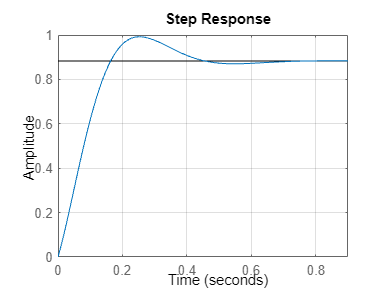

figure
step(GLC)
grid on

info=stepinfo(GLC)

info = struct with fields:
         RiseTime: 0.1212
    TransientTime: 0.4149
     SettlingTime: 0.4149
      SettlingMin: 0.8101
      SettlingMax: 0.9921
        Overshoot: 12.4380
       Undershoot: 0
             Peak: 0.9921
         PeakTime: 0.2517


ts=info.RiseTime

ts = 0.1212

ess=1-(info.Peak)

ess = 0.0079

ts95=info.SettlingTime

ts95 = 0.4149

## Controlador PI (KP, KI)

m=1

m = 1

b=10

b = 10

k=20

k = 20

num=[1]

num = 1

den=[m b k]

den =      1    10    20


P=tf(num,den)

P =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


kp=100

kp = 100

ki=.3

ki = 0.3000

C1=kp

C1 = 100

C2=tf([ki],[1 0])

C2 =
 
  0.3
  ---
   s
 
Continuous-time transfer function.
Model Properties


C=C1+C2

C =
 
  100 s + 0.3
  -----------
       s
 
Continuous-time transfer function.
Model Properties


CP=series(C,P)

CP =
 
      100 s + 0.3
  -------------------
  s^3 + 10 s^2 + 20 s
 
Continuous-time transfer function.
Model Properties


GLC=feedback(CP,1)

GLC =
 
         100 s + 0.3
  --------------------------
  s^3 + 10 s^2 + 120 s + 0.3
 
Continuous-time transfer function.
Model Properties


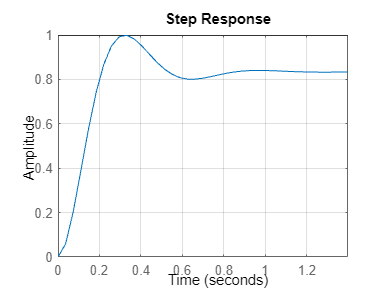

figure
step(GLC)
grid on

info=stepinfo(GLC)

info = struct with fields:
         RiseTime: 0.1457
    TransientTime: 0.7977
     SettlingTime: 0.7977
      SettlingMin: 0.8012
      SettlingMax: 0.9992
        Overshoot: 18.7536
       Undershoot: 0
             Peak: 0.9992
         PeakTime: 0.3315


ts=info.RiseTime

ts = 0.1457

ess=1-(info.Peak)

ess = 8.1769e-04

ts95=info.SettlingTime

ts95 = 0.7977

## Controlador PID (KP, KI, KD)

m=1

m = 1

b=10

b = 10

k=20

k = 20

num=[1]

num = 1

den=[m b k]

den =      1    10    20


P=tf(num,den)

P =
 
         1
  ---------------
  s^2 + 10 s + 20
 
Continuous-time transfer function.
Model Properties


kp=50

kp = 50

ki=0.03

ki = 0.0300

kd=1

kd = 1

C1=kp

C1 = 50

C2=tf([ki],[1 0])

C2 =
 
  0.03
  ----
   s
 
Continuous-time transfer function.
Model Properties


C3=tf([kd 0],[1])

C3 =
 
  s
 
Continuous-time transfer function.
Model Properties


C=C1+C2+C3

C =
 
  s^2 + 50 s + 0.03
  -----------------
          s
 
Continuous-time transfer function.
Model Properties


CP=series(C,P)

CP =
 
   s^2 + 50 s + 0.03
  -------------------
  s^3 + 10 s^2 + 20 s
 
Continuous-time transfer function.
Model Properties


GLC=feedback(CP,1)

GLC =
 
      s^2 + 50 s + 0.03
  --------------------------
  s^3 + 11 s^2 + 70 s + 0.03
 
Continuous-time transfer function.
Model Properties


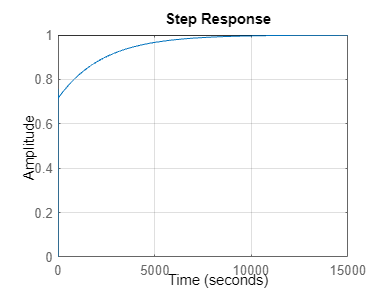

figure
step(GLC)
grid on

info=stepinfo(GLC)

info = struct with fields:
         RiseTime: 2.4492e+03
    TransientTime: 6.2043e+03
     SettlingTime: 6.2043e+03
      SettlingMin: 0.9000
      SettlingMax: 0.9998
        Overshoot: 0
       Undershoot: 0
             Peak: 0.9998
         PeakTime: 1.6731e+04


ts=info.RiseTime

ts = 2.4492e+03

ess=1-(info.Peak)

ess = 2.1955e-04

ts95=info.SettlingTime

ts95 = 6.2043e+03